% Definir la carpeta que contiene los archivos de audio
dataFolder = "C:\Users\alfre\Music\Audios_Reto2";

% Crear el audioDatastore utilizando los archivos en la carpeta
ads = audioDatastore(dataFolder, ...
    'IncludeSubfolders', true, ...
    'FileExtensions', {'.wav', '.flac', '.ogg', '.opus', '.mp4', '.m4a'}, ...
    'LabelSource', 'foldernames');

ads

ads =   audioDatastore with properties:

                       Files: {
                              'C:\Users\alfre\Music\Audios_Reto2\Daniel\dani10_aug1.wav';
                              'C:\Users\alfre\Music\Audios_Reto2\Daniel\dani10_aug10.wav';
                              'C:\Users\alfre\Music\Audios_Reto2\Daniel\dani10_aug2.wav'
                               ... and 1297 more
                              }
                     Folders: {
                              'C:\Users\alfre\Music\Audios_Reto2'
                              }
                      Labels: [Daniel; Daniel; Daniel ... and 1297 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
           OutputEnvironment: 'cpu'
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "opus"    "mp3"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"



% Dividir los datos en entrenamiento (80%) y prueba (20%)
[adsTrain, adsTest] = splitEachLabel(ads, 0.8);

adsTrain

adsTrain =   audioDatastore with properties:

                       Files: {
                              'C:\Users\alfre\Music\Audios_Reto2\Daniel\dani10_aug1.wav';
                              'C:\Users\alfre\Music\Audios_Reto2\Daniel\dani10_aug10.wav';
                              'C:\Users\alfre\Music\Audios_Reto2\Daniel\dani10_aug2.wav'
                               ... and 1037 more
                              }
                     Folders: {
                              'C:\Users\alfre\Music\Audios_Reto2'
                              }
                      Labels: [Daniel; Daniel; Daniel ... and 1037 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
           OutputEnvironment: 'cpu'
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "opus"    "mp3"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"



% Contar la cantidad de archivos por etiqueta
trainDatastoreCount = countEachLabel(adsTrain)

trainDatastoreCount = 13×2 table
     Label     Count
    _______    _____

    Daniel      80  
    Elias       80  
    JP          80  
    Mariam      80  
    Oscar       80  
    Paola       80  
    Yestly      80  
    adrian      80  
    alfredo     80  
    bruno       80  
    fredy       80  
    olguin      80  
    yona        80  


adsTest

adsTest =   audioDatastore with properties:

                       Files: {
                              'C:\Users\alfre\Music\Audios_Reto2\Daniel\dani8_aug1.wav';
                              'C:\Users\alfre\Music\Audios_Reto2\Daniel\dani8_aug10.wav';
                              'C:\Users\alfre\Music\Audios_Reto2\Daniel\dani8_aug2.wav'
                               ... and 257 more
                              }
                     Folders: {
                              'C:\Users\alfre\Music\Audios_Reto2'
                              }
                      Labels: [Daniel; Daniel; Daniel ... and 257 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
           OutputEnvironment: 'cpu'
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "opus"    "mp3"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"


testDatastoreCount = countEachLabel(adsTest)

testDatastoreCount = 13×2 table
     Label     Count
    _______    _____

    Daniel      20  
    Elias       20  
    JP          20  
    Mariam      20  
    Oscar       20  
    Paola       20  
    Yestly      20  
    adrian      20  
    alfredo     20  
    bruno       20  
    fredy       20  
    olguin      20  
    yona        20  



% Leer un archivo de entrenamiento para obtener la tasa de muestreo
[sampleTrain, dsInfo] = read(adsTrain);
reset(adsTrain)



% Configurar el extractor de características
fs = dsInfo.SampleRate;
windowLength = round(0.03 * fs);  % Longitud de la ventana de 30 ms
overlapLength = round(0.025 * fs);  % Superposición de 25 ms
afe = audioFeatureExtractor(SampleRate = fs, ...
    Window = hamming(windowLength, "periodic"), OverlapLength = overlapLength, ...
    zerocrossrate = true, shortTimeEnergy = true, pitch = true, mfcc = true);

% Obtener el mapa de las características
featureMap = info(afe)

featureMap = struct with fields:
               mfcc: [1 2 3 4 5 6 7 8 9 10 11 12 13]
              pitch: 14
      zerocrossrate: 15
    shortTimeEnergy: 16



% Inicializar las matrices de características y etiquetas
features = [];
labels = [];
energyThreshold = 0.35;
zcrThreshold = 0.22;


allFeatures = extract(afe,adsTrain);
allLabels = adsTrain.Labels;

for ii = 1:numel(allFeatures)

    thisFeature = allFeatures{ii};

    isSpeech = thisFeature(:,featureMap.shortTimeEnergy) > energyThreshold;
    isVoiced = thisFeature(:,featureMap.zerocrossrate) < zcrThreshold;

    voicedSpeech = isSpeech & isVoiced;

    thisFeature(~voicedSpeech,:) = [];
    thisFeature(:,[featureMap.zerocrossrate,featureMap.shortTimeEnergy]) = [];
    label = repelem(allLabels(ii),size(thisFeature,1));
    
    features = [features;thisFeature];
    labels = [labels,label];
end

% Normalizar las características
M = mean(features, 1);
S = std(features, [], 1);
features = (features - M) ./ S;


trainedClassifier = fitcknn(features,labels, ...
    Distance="euclidean", ...
    NumNeighbors=13, ...
    DistanceWeight="squaredinverse", ...
    Standardize=false, ...
    ClassNames=unique(labels));
k = 13;
group = labels;
c = cvpartition(group,KFold=k); % 10-fold stratified cross validation
partitionedModel = crossval(trainedClassifier,CVPartition=c);

% Calcular la exactitud de validación cruzada
validationAccuracy = 1 - kfoldLoss(partitionedModel, 'LossFun', 'ClassifError');
fprintf('\nValidation accuracy = %.2f%%\n', validationAccuracy * 100);


Validation accuracy = 97.16%


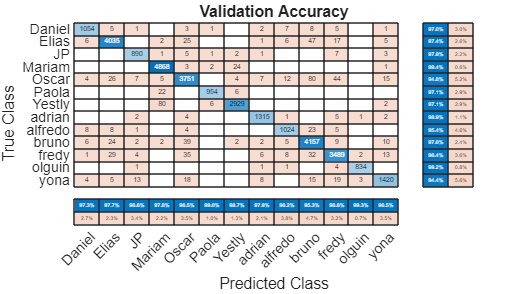


% Predicciones de validación
validationPredictions = kfoldPredict(partitionedModel);

% Matriz de confusión de la validación
figure('Units', 'normalized', 'Position', [0.4 0.4 0.4 0.4]);
confusionchart(labels, validationPredictions, 'Title', 'Validation Accuracy', ...
    'ColumnSummary', 'column-normalized', 'RowSummary', 'row-normalized');

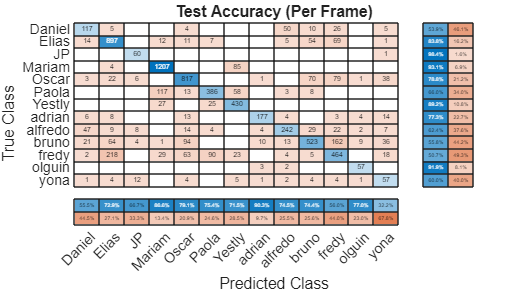


% Extracción de características para el conjunto de prueba
features = [];
labels = [];
numVectorsPerFile = [];

allFeatures = extract(afe, adsTest);
allLabels = adsTest.Labels;

for ii = 1:numel(allFeatures)
    thisFeature = allFeatures{ii};

    isSpeech = thisFeature(:,featureMap.shortTimeEnergy) > energyThreshold;
    isVoiced = thisFeature(:,featureMap.zerocrossrate) < zcrThreshold;

    voicedSpeech = isSpeech & isVoiced;

    thisFeature(~voicedSpeech,:) = [];
    numVec = size(thisFeature,1);
    thisFeature(:,[featureMap.zerocrossrate,featureMap.shortTimeEnergy]) = [];
    
    label = repelem(allLabels(ii),numVec);
    
    numVectorsPerFile = [numVectorsPerFile,numVec];
    features = [features;thisFeature];
    labels = [labels,label];
end

features = (features-M)./S;

prediction = predict(trainedClassifier,features);
prediction = categorical(string(prediction));

figure(Units="normalized",Position=[0.4 0.4 0.4 0.4])
confusionchart(labels(:),prediction,title="Test Accuracy (Per Frame)", ...
    ColumnSummary="column-normalized",RowSummary="row-normalized");

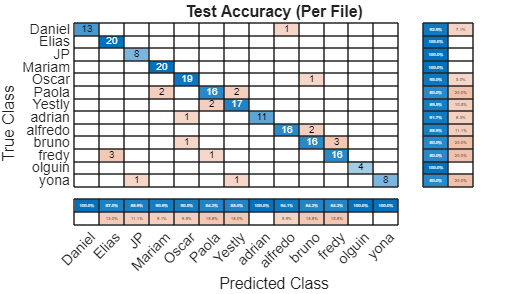


r2 = prediction(1:numel(adsTest.Files));
idx = 1;
for ii = 1:numel(adsTest.Files)
    r2(ii) = mode(prediction(idx:idx+numVectorsPerFile(ii)-1));
    idx = idx + numVectorsPerFile(ii);
end

figure(Units="normalized",Position=[0.4 0.4 0.4 0.4])
confusionchart(adsTest.Labels,r2,title="Test Accuracy (Per File)", ...
    ColumnSummary="column-normalized",RowSummary="row-normalized");